# week2 exercise.m

% safety first
close all;
clear all;

## Project 2

Randomly select N (let's say 10) years out of the existing data from the last 141 years, and average July temperature of Atlanta for those years. Repeat this 1,000 times. Will it follow CLT?

## get the data

atlanta_temperature= ... 
    xlsread('ATL_MonMeanTemp_1879_2020.xls');

#### line plot for the entire dataset... aka spagetti plot... not very insightful

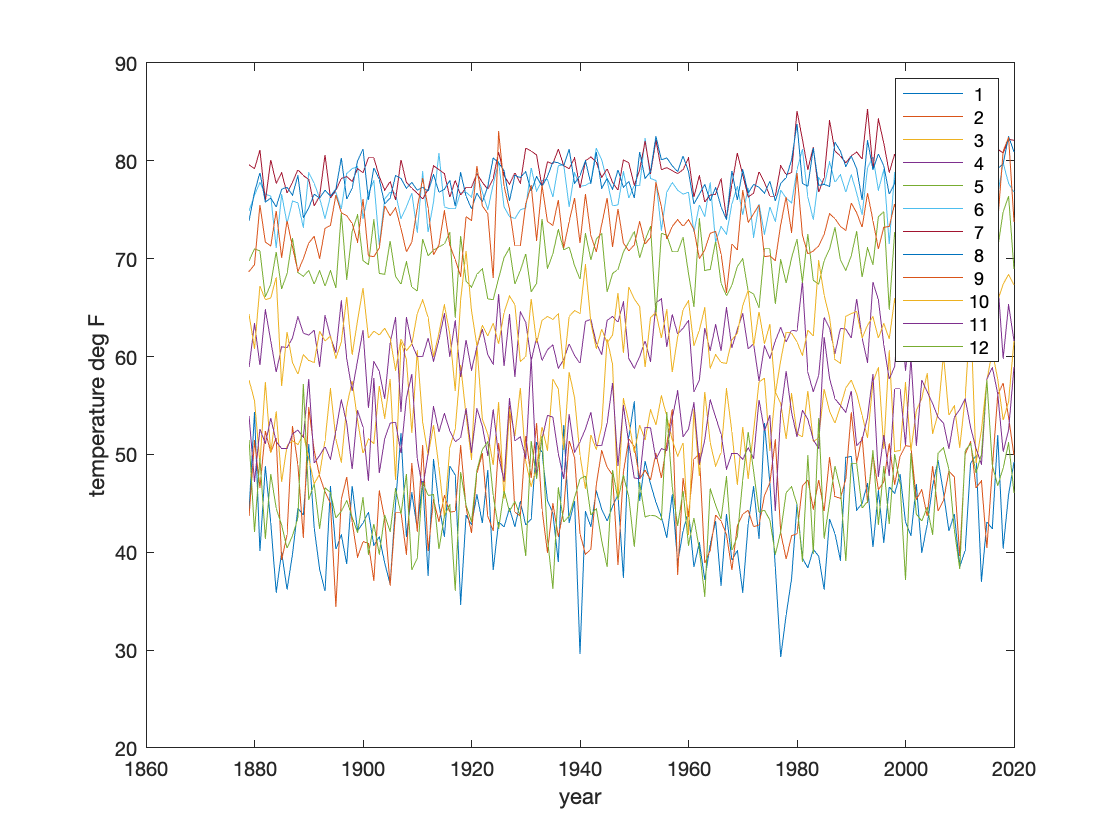

year=atlanta_temperature(:,1);
temp=atlanta_temperature(:,2:13);
plot(year,temp);
xlabel('year');
ylabel('temperature deg F');
legend(num2str([1:12]'));

%axis([1879 2050 30 90]);

#### Contour plot for the entire dataset

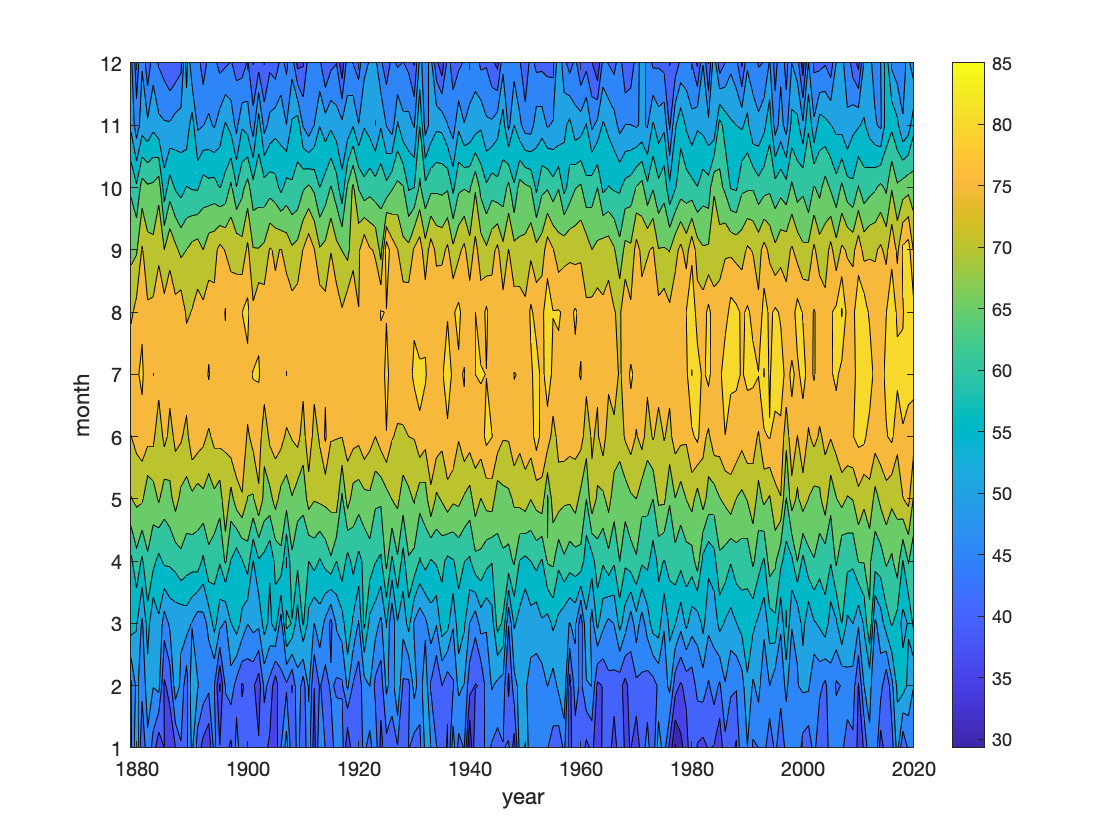

mon=1:12;
figure;
contourf(year,mon,temp');
colorbar;
xlabel('year')
ylabel('month')

## extract july mean temp

july = atlanta_temperature(:,8);
mu=mean(july);
sig=std(july);
disp(['mean july temp is ',num2str(mu),' deg F']);

mean july temp is 79.0775 deg F


disp(['std of july temp is ',num2str(sig),' deg F']);

std of july temp is 2.0253 deg F


## Bootstrap: repeat resampling

N=10;     % N = sample size
K=1000;   % K times repeat sampling
for n=1:K
   data  = randsample(july,N);
   M(n)  = mean(data);
end

## 1. Mean of sample mean is true mean

Mmean=mean(M);
disp(['Mean of sample mean is ',num2str(Mmean),' deg F'])

Mean of sample mean is 79.1056 deg F


## 2. Standard deviation of sample mean is standard error (SE)

Mstd=std(M);
SE = sig/sqrt(N);
disp(['std of sample mean is ',num2str(Mstd)]);

std of sample mean is 0.60337


disp(['sigma/sqrt(N) is ',num2str(SE)]);

sigma/sqrt(N) is 0.64046


## 3. Sample mean follows Gaussian distribution

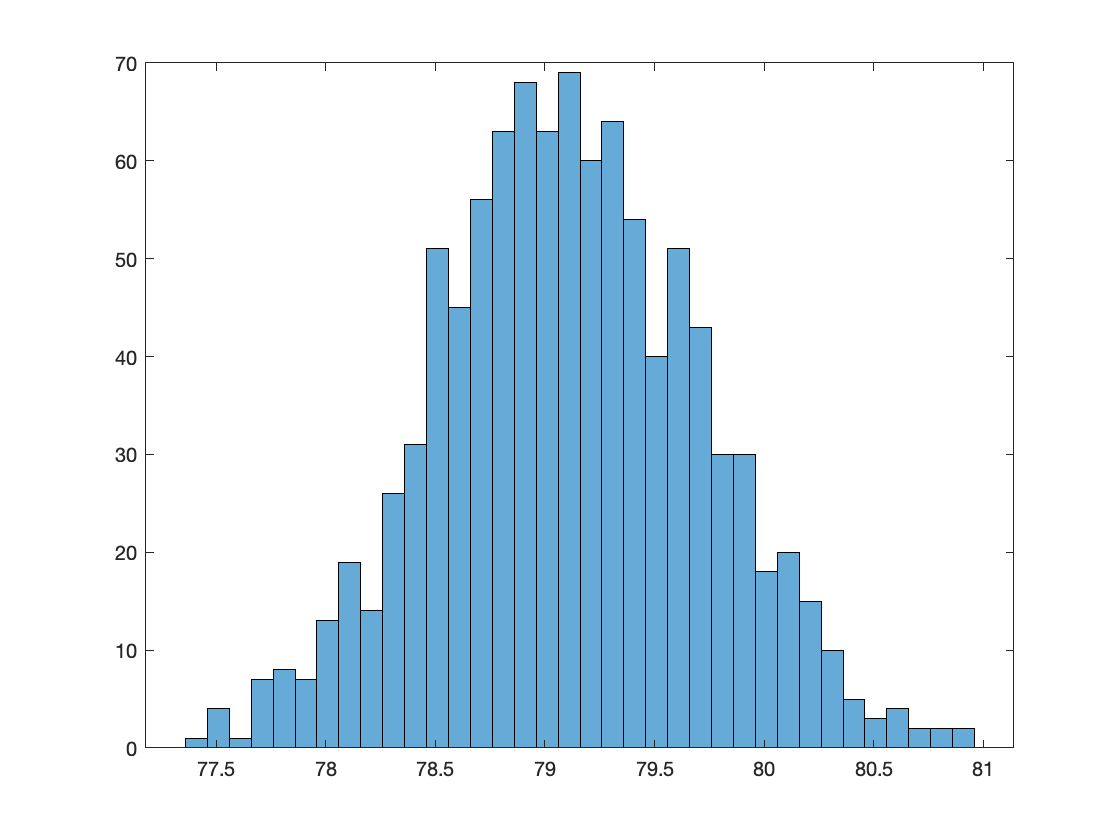

figure(1);
dx=.1;
bins=min(M):dx:max(M);
histogram(M,bins);

## Overlay gaussian

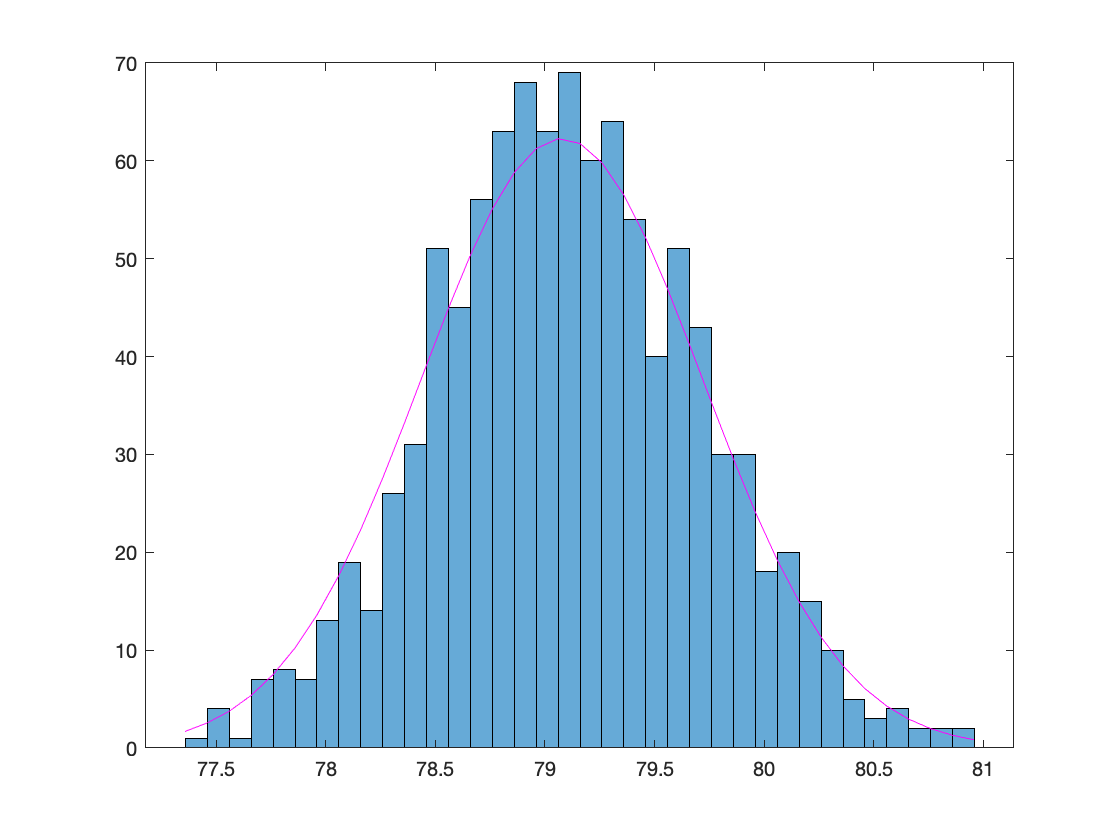

x=min(M):dx:max(M);
f=K*dx/(sqrt(2*pi)*SE)*exp(-0.5*((x-mu)/SE).^2);
hold on;
plot(x,f,'m-');

## calculate 95 percentile

t95=prctile(M,95);
disp(['95 percentile temp is ',num2str(t95)]);

95 percentile temp is 80.11


## calculate 99 percentile

t99=prctile(M,99);
disp(['99 percentile temp is ',num2str(t99)]);

99 percentile temp is 80.58


## calculate last N years average

l10=mean(july(end-N+1:end));
disp(['Last N year mean temp is ',num2str(l10)]);

Last N year mean temp is 81.26
